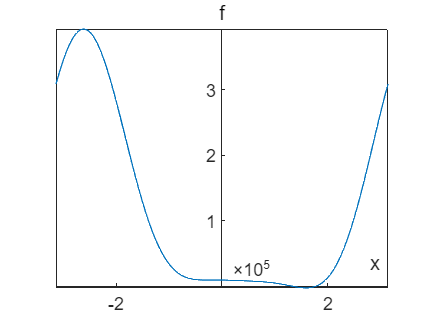

L1=3;
L2=3*sqrt(2);
L3=3;
gamma=pi/4;
p1=5;
p2=4;
p3=3;
x1=5;
x2=0;
y2=6;
ezplot(@f,[-pi,pi])
ax=gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
axis([-inf inf -inf inf]);

function out=f(theta)
format long;
L1=3;
L2=3*sqrt(2);
L3=3;
gamma=pi/4;
p1=5;
p2=4;
p3=3;
x1=5;
x2=0;
y2=6;
A2=L3.*cos(theta)-x1;
B2=L3.*sin(theta);
A3=L2.*(cos(theta).*cos(gamma)-sin(theta).*sin(gamma))-x2;
B3=L2.*(cos(theta).*sin(gamma)+sin(theta).*cos(gamma))-y2;
D=2.*(A2.*B3-B2.*A3);
M1=p2.^2-p1.^2-A2.^2-B2.^2;
M2=p3.^2-p1.^2-A3.^2-B3.^2;
N1=B3.*M1-B2.*M2;
N2=-A3.*M1+A2.*M2;
out=N1.^2+N2.^2-p1.^2*D.^2;
end
